Observations

numObs = 3;
obsInfo = rlNumericSpec([numObs 1], 'LowerLimit', [-inf -inf 0]', 'UpperLimit', [inf inf inf]');
obsInfo.Name = 'integrated error, error, and gap';

Actions

numAct = 1;
actInfo = rlNumericSpec([numAct 1]);
actInfo.Name = 'Voltage';

mdl = 'tf_rl_reward2';
open_system(mdl)

%blk = mdl + '/RL Agent';
env = rlSimulinkEnv(mdl, [mdl '/RL Agent'], obsInfo, actInfo);

obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: [3×1 double]
     UpperLimit: [3×1 double]
           Name: "integrated error, error, and gap"
    Description: [0×0 string]
      Dimension: [3 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "Voltage"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"



%env.ResetFcn = @(in)localResetFcn(in); (without randomising initial height)

%validateEnvironment(env)
Ts = 0.001;     % originally 1.0
Tf = 200;

%reinforcementLearningDesigner

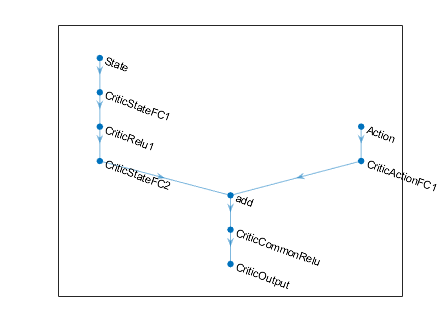

statePath = [
    imageInputLayer([numObs 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(50,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(25,'Name','CriticStateFC2')];

actionPath = [
    imageInputLayer([numAct 1 1],'Normalization','none','Name','Action')
    fullyConnectedLayer(25,'Name','CriticActionFC1')];

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

figure
plot(criticNetwork)


criticOpts = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1,'UseDevice','gpu');

critic = rlQValueRepresentation(criticNetwork, obsInfo, actInfo, 'Observation', {'State'}, 'Action', {'Action'});
%critic = rlQValueFunction(criticNetwork, obsInfo, actInfo, ObservationInputNames="obsIn", ActionInputNames="actIn");

actorNetwork = [
    imageInputLayer([numObs 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC')
    tanhLayer('Name','actorTanh')
    fullyConnectedLayer(numAct,'Name','Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1,'UseDevice','gpu');

%actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'
actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6);
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',800);

trainingStats = train(agent,env,trainOpts);